Biosensoren: Uebung 1

Aufgabe 1: Sinus-Signal

- f$f_{\textrm{Signal}}$= 1Hz

- Amlitude = 5V

- $f_{\textrm{sample}}$= 100 Hz

- Fensterlänge = 2 s

fsignal = 1; % Hz
twindow = 2; %s
fs = 100; % Hz
a = 5; % V
step = 1/fs; %s

% time vector
t = 0:step:twindow;

% Anzahl Eintraege ungerade
if(mod(length(t),2))
    t = t(1:end-1);
end

signal = a*sin(2*pi*fsignal*t) % Hs*s = 1

signal =          0    0.3140    0.6267    0.9369    1.2434    1.5451    1.8406    2.1289    2.4088    2.6791    2.9389    3.1871    3.4227    3.6448    3.8526    4.0451    4.2216    4.3815    4.5241    4.6489    4.7553    4.8429    4.9114    4.9606    4.9901    5.0000    4.9901    4.9606    4.9114    4.8429    4.7553    4.6489    4.5241    4.3815    4.2216    4.0451    3.8526    3.6448    3.4227    3.1871    2.9389    2.6791    2.4088    2.1289    1.8406    1.5451    1.2434    0.9369    0.6267    0.3140


Darstellung des Signals:

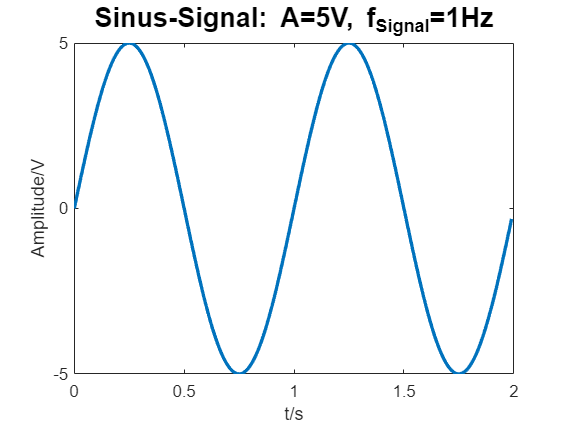

figure;
plot(t,signal,'LineWidth',2)
xlabel('t/s')
ylabel('Amplitude/V')
title(['Sinus-Signal: A=' num2str(a) 'V, f_{Signal}=' num2str(fsignal) 'Hz'],'FontSize',16)


disp(['Signallaenge: ' num2str(length(t))] );

Signallaenge: 200


Darstellung der zeitlichen Diskretisierung

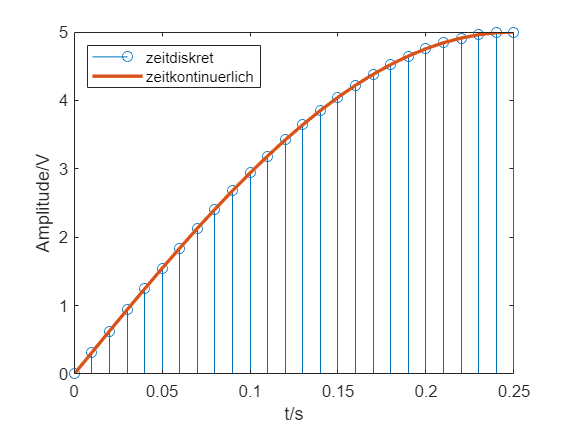

figure
stem(t,signal)
% stairs(t,signal)
hold on
plot(t,signal,'LineWidth',2)
hold off
xlim([0 0.25])
xlabel('t/s')
legend('zeitdiskret','zeitkontinuerlich','Location','NorthWest')
ylabel('Amplitude/V')

Quantisierungseffekt

- 3-bit-Quantisierung

quantBit = 3;
quantNum = 2^quantBit;
quantStep = 2*a/(quantNum-1);

Quantisierung mit quantiz;

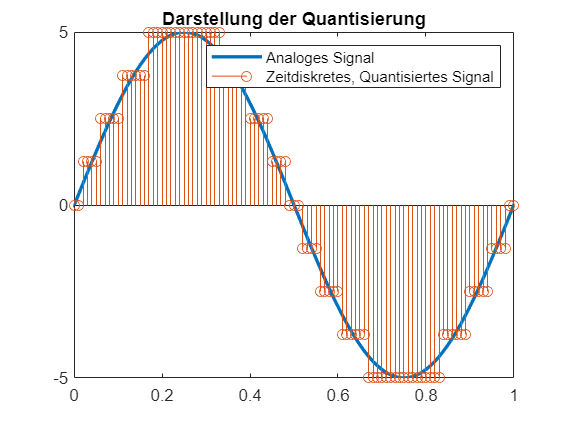

%Wertebereich 
partition = linspace(-a,a,quantNum);
partition = linspace(-a +  quantStep/2, a - quantStep/2, quantNum);
% Schritte
codebook = linspace(-a,a,quantNum+1);

[index, quants]= quantiz(signal,partition, codebook);

figure
plot(t,signal, 'LineWidth', 2)
hold on
stem(t,quants)
hold off
xlim([0 1])
title('Darstellung der Quantisierung')
legend('Analoges Signal','Zeitdiskretes, Quantisiertes Signal')

Quantisierungsrauschen

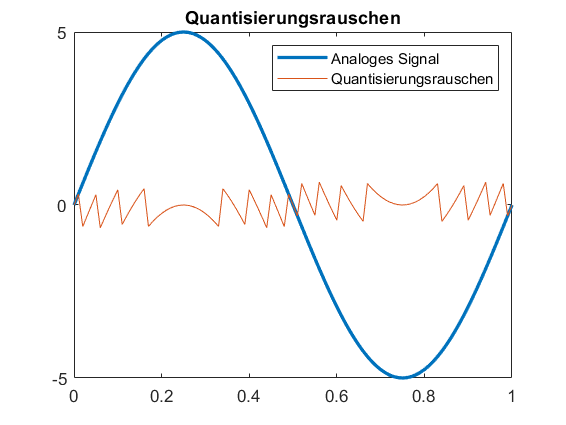

figure
plot(t,signal,'LineWidth',2)
hold on
%stem(t,quants)
plot(t,signal-quants)
hold off
xlim([0 1])
title('Quantisierungsrauschen')
legend('Analoges Signal','Quantisierungsrauschen')

Aufgabe 2: Fourier-Transformation

Überlagerung von 3 Signalen:

- Signal 1: 1 Hz, A=5V

- Signal 2: 10 Hz, A=2V

- Signal 3: 0.5 Hz, A=10

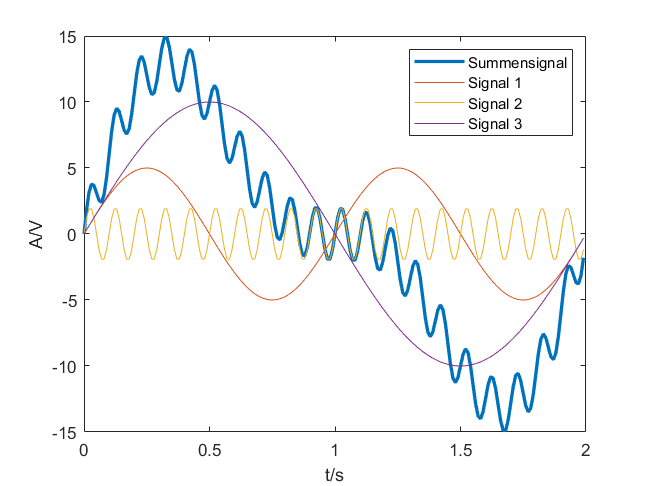

sig1 = signal;
sig2 = 2*sin(2*pi*10*t);
sig3= 10*sin(2*pi*0.5*t);

sumSig = sig1 + sig2 + sig3;

figure
plot(t,sumSig, 'LineWidth', 2)
hold on
plot(t,[sig1;sig2;sig3])
xlabel('t/s')
ylabel('A/V')
legend('Summensignal','Signal 1','Signal 2','Signal 3')

FFT: zunächst verwenden wir** stem();**

% Laenge des Signals
L = length(sumSig);

% Fast Fourier Transformation
Y = fft(sumSig);

% Zweiseitige FFT
P2 = abs(Y/L);
% Einseitige FFT
P1 = P2(1:(L/2)+1);
P1(2:end-1)=2*P1(2:end-1);

% Frequenz Spektrum
f = fs*(0:(L/2))/L;

Rasuchen:

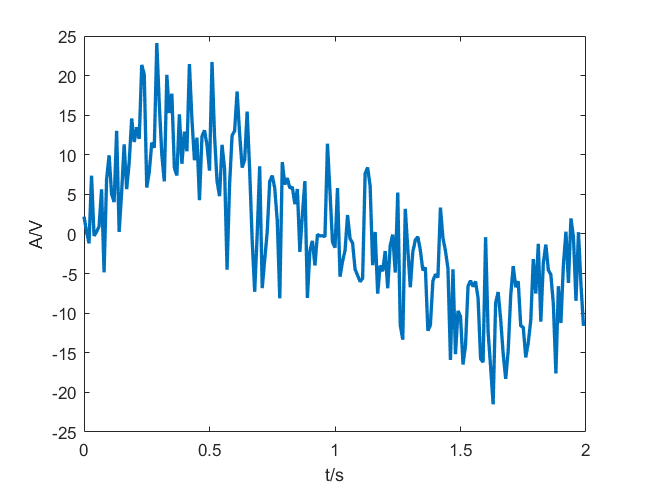

signNoise= 5* randn(1, length (t));

figure
plot(t,signNoise+sumSig, 'LineWidth', 2)
xlabel('t/s')
ylabel('A/V')

FFT:

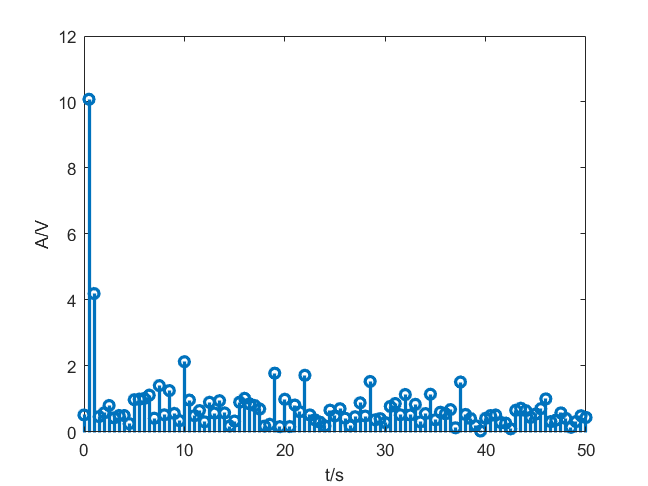

% Laenge des Signals
L = length(sumSig);

% Fast Fourier Transformation
Y = fft(sumSig+signNoise);

% Zweiseitige FFT
P2 = abs(Y/L);
% Einseitige FFT
P1 = P2(1:(L/2)+1);
P1(2:end-1)=2*P1(2:end-1);

% Frequenz Spektrum
f = fs*(0:(L/2))/L;

fftVerrauscht = P1;

figure
stem(f,P1,'LineWidth',2)
xlabel('t/s')
ylabel('A/V')

Mitteln:

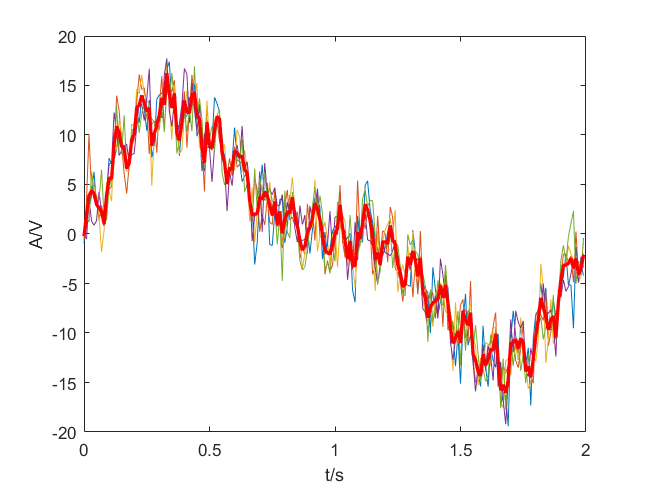

noiseFact = 2;
sigRausch1 = noiseFact * randn(1,length(t));
sigRausch2 = noiseFact * randn(1,length(t));
sigRausch3 = noiseFact * randn(1,length(t));
sigRausch4 = noiseFact * randn(1,length(t));
sigRausch5 = noiseFact * randn(1,length(t));

sig1 = sumSig + sigRausch1;
sig2 = sumSig + sigRausch2;
sig3 = sumSig + sigRausch3;
sig4 = sumSig + sigRausch4;
sig5 = sumSig + sigRausch5;

avgSig = mean([sig1; sig2; sig3; sig4; sig5],1);

figure
plot(t, [sig1; sig2; sig3; sig4; sig5])
hold on
plot(t, avgSig, 'LineWidth',2, 'Color','red')
hold off
xlabel('t/s')
ylabel('A/V')

Vergleich mit Original:

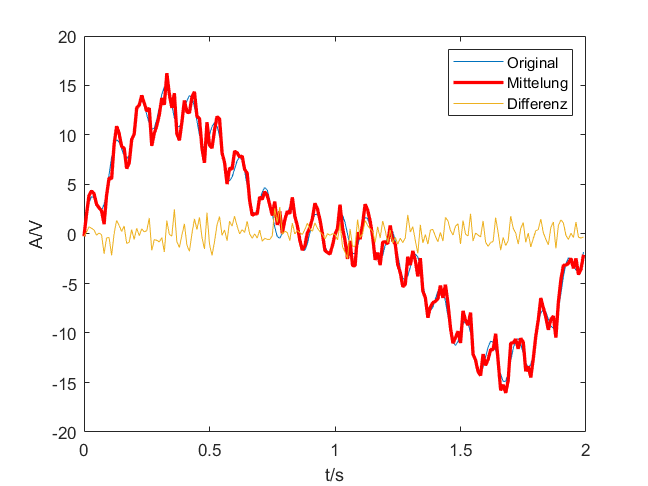

figure
plot(t, sumSig)
hold on
plot(t, avgSig, 'LineWidth',2, 'Color','red')
plot(t, avgSig-sumSig)
hold off
legend('Original','Mittelung','Differenz')
xlabel('t/s')
ylabel('A/V')

Verbesserung des SNR (signal noise ratio)

% Theoretisch
snrTheo = noiseFact/sqrt(5)

snrTheo = 0.8944


% gemessen
snrMeas = std(avgSig-sumSig)

snrMeas = 0.9717

Vergleich FFT von gemitteltem und verrauschtem Signal:

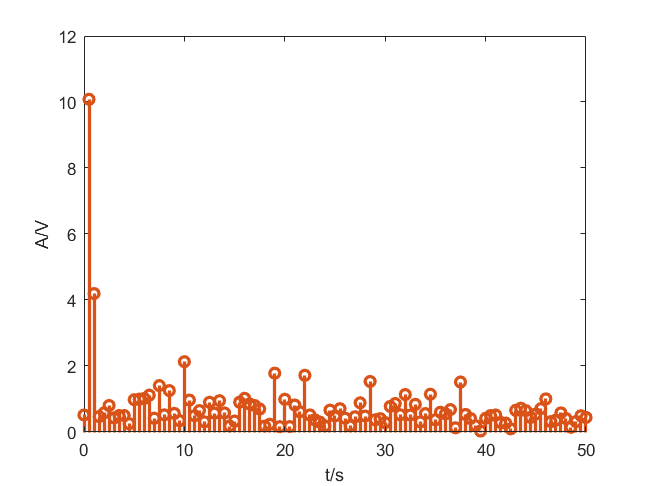

% Laenge des Signals
L = length(sumSig);

% Fast Fourier Transformation
Y1 = fft(avgSig);

% Zweiseitige FFT
P2 = abs(Y/L);
% Einseitige FFT
P1 = P2(1:(L/2)+1);
P1(2:end-1)=2*P1(2:end-1);

fftAvg= P1;
% Frequenz Spektrum
f = fs*(0:(L/2))/L;

figure
stem(f,fftVerrauscht,'LineWidth',2)
hold on
stem(f, fftAvg,'LineWidth',2 )
hold off
xlabel('t/s')
ylabel('A/V')

Störfrequenz

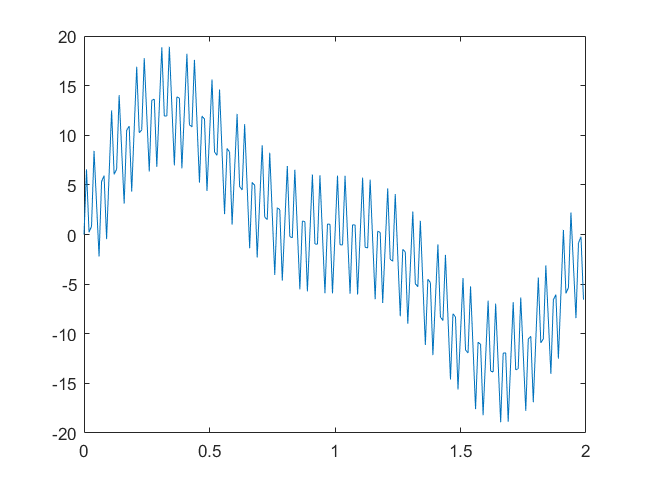

fStoer= 30; %Hz
sigStoer= 5* sin(2*pi*fStoer*t);

sigNoiseStoer= sumSig+ sigStoer;

figure
plot(t,sigNoiseStoer)

FFT

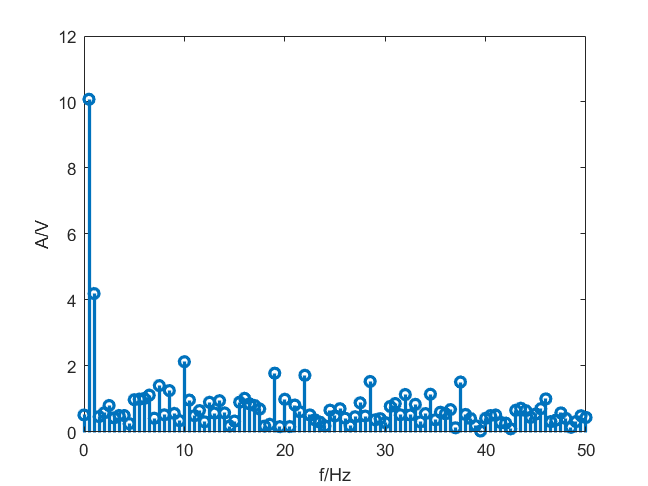

% Laenge des Signals
L = length(sumSig);

% Fast Fourier Transformation
Y1 = fft(sigNoiseStoer);

% Zweiseitige FFT
P2 = abs(Y/L);
% Einseitige FFT
P1 = P2(1:(L/2)+1);
P1(2:end-1)=2*P1(2:end-1);

figure
stem(f,P1,'LineWidth',2)
xlabel('f/Hz')
ylabel('A/V')

Filtern durch Nullsetzen:

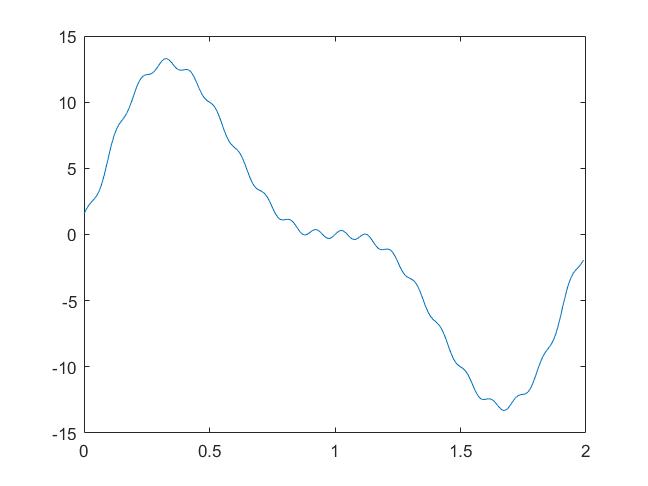

sigFilt = lowpass(sigNoiseStoer,5/50);

figure
plot(t,sigFilt);

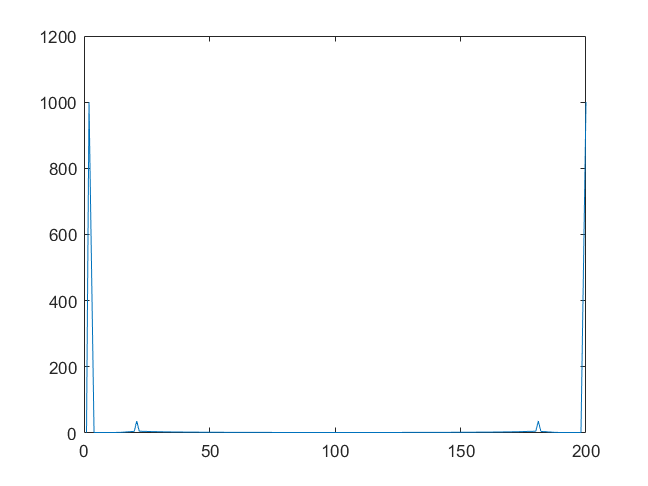


figure
plot(abs(fft(sigFilt)))